clear; clc; close all

## LOADING DATASET

filename='Explant_ResponseGroup_Allprot_DEGs.xlsx';
% note: duplicated gene removed from Allprot dat.

tbl_exp_dat=readtable(filename,...
    'Sheet','DEG expression');

tbl_target_class=readtable(filename,...
    'Sheet','Target labels');

tbl_deg_pval=readtable(filename,...
    'Sheet','DEG pvals');

% expression data (to be normalized)
exp_dat_raw=table2array(tbl_exp_dat(:,2:end));
% gene names (input variable)
gene_name=tbl_exp_dat.GeneName;
% target lables (output labels)
response_dat = table2array(tbl_target_class);
% p-value (just for inform)
p_val=tbl_deg_pval.DEGs_Pval;

## Expression data normalization

tmp_min = repmat(min(exp_dat_raw')',1,size(exp_dat_raw,2));
tmp_max = repmat(max(exp_dat_raw')',1,size(exp_dat_raw,2));
input_dat_norm = (exp_dat_raw -  tmp_min)./(tmp_max - tmp_min);

## RUN THE SIMULATION

Expression_ML/Response_ML Input-train Input-test Target-train Target-test

num_genes= size(input_dat_norm,1);
num_cross_val = 50;
num_of_sample = size(input_dat_norm,2);


% random sampling for train (80%) and test (20%)
for ii = 1:num_cross_val
    rng(ii); % random number seed for reproducibility
    [train_sample_idx(ii,:),~,test_sample_idx(ii,:)] = dividerand(num_of_sample,0.8,0.0,0.2);
end

nd1 = num_cross_val;
% cross-validation = 50
nd2 = num_genes;

parfor  masterIDX = 1:nd1*nd2
    
    disp(masterIDX)
    
    [idx1,idx2]=ind2sub([nd1,nd2],masterIDX);
    
    % copy variables for par
    input_dat_norm_par = input_dat_norm;
    train_sample_idx_par = train_sample_idx;
    test_sample_idx_par = test_sample_idx;
    response_dat_par = response_dat;
    
    % organize input data to be used for learning (gradual increment)
    input_dat_organized = input_dat_norm_par(1:idx2,:);
    
    
    % pick up samples for training an test
    train_idx=train_sample_idx_par(idx1,:);
    test_idx=test_sample_idx_par(idx1,:);
    
    % Train & Test data
    predictor_train = input_dat_organized(:,train_idx); % training input
    predictor_test = input_dat_organized(:,test_idx); % test input
    
    class_label_train = response_dat_par(train_idx);
    class_label_true = response_dat_par(test_idx);
    
    
    % SVM options
    svmtemp=templateSVM('Standardize',1,...
        'KernelFunction','linear');
    Mdl = fitcecoc(predictor_train',class_label_train',...
        'Learners',svmtemp,...
        'ClassNames',{'NR','RD','PR'});
    % CVMdl = crossval(Mdl)
    % genError = kfoldLoss(CVMdl)
    
    % Model prediction
    predicted_class_label_par(:,masterIDX) = predict(Mdl,predictor_test');
    %[predict_class_par(:,masterIDX),~,~,cnum(:,:,masterIDX)]=predict(Mdl,input_test');
    true_class_label_par(:,masterIDX) = class_label_true';
    
end

    50

   100

   150

   200

   250

   300

   350

   400

    49

    48

    47

    46

    45

    99

    98

    97

    96

    95

    94

   149

   148

   147

   146

   145

   144

   143

   142

   141

   140

   139

   199

   198

   197

   196

   195

   194

   193

   192

   191

   190

   249

   248

   247

   246

   245

   244

   243

   242

   241

   240

   239

   299

   298

   297

   296

   295

   294

   293

   292

   291

   290

   289

   349

   348

   347

   346

   345

   344

   343

   342

   341

   340

   339

   399

   398

   397

   396

   395

   394

   393

   392

   391

   390

   389

    44

    43

    42

    41

    40

    39

    93

    92

    91

    90

    89

   138

   137

   136

   135

   134

   133

   132

   131

   130

   189

   188

   187

   186

   185

   184

   183

   182

   181

   238

   237

   236

   235

   234

   233

   232

   231

   230

   229

   288

   287





% reshaping the parfor-result
[nr1,~] = size(predicted_class_label_par);
predicted_class_label = reshape(predicted_class_label_par,[nr1,nd1,nd2]);

[nr2,~] = size(true_class_label_par);
true_class_label = reshape(true_class_label_par,[nr2,nd1,nd2]);

% [nr3,nc3,~] = size(cnum);
% predict_prob = reshape(cnum,[nr3,nc3,nd1,nd2]);

post-processing

for masterIDX = 1:nd1*nd2
    
    [idx1,idx2]=ind2sub([nd1,nd2],masterIDX);
    
    
    %     tmp_predicted_output(:,1) = predict_class(:,idx1,idx2);
    %     tmp_target_output_known(:,1)=known_class(:,idx1,idx2);
    
    [cmat,~] = confusionmat(true_class_label(:,idx1,idx2),predicted_class_label(:,idx1,idx2));
    score_mat_par(masterIDX)= sum(diag(cmat)/length(true_class_label(:,idx1,idx2)));
    
end

% reshaping the parfor-result
[nr1,~] = size(score_mat_par);
score_mat = reshape(score_mat_par,[nd1,nd2]);

% averaged prediction accuracy
predict_acc = mean(score_mat);

Plot Prediction accuracy

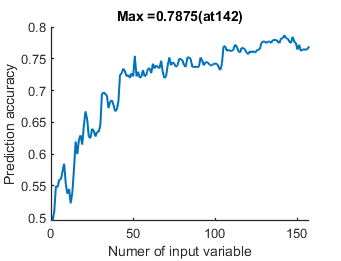

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure('Position',[680   717   341   261])
plot(1:num_genes,predict_acc,'LineWidth',1.5)
set(gca,'LineWidth',1)

xlabel('Numer of input variable')
ylabel('Prediction accuracy')
pbaspect([4 3 1]/4)
box off


maxloc = find(predict_acc==max(predict_acc));
title(strcat('Max = ',num2str(predict_acc(maxloc)),'(at',num2str(maxloc),')'))

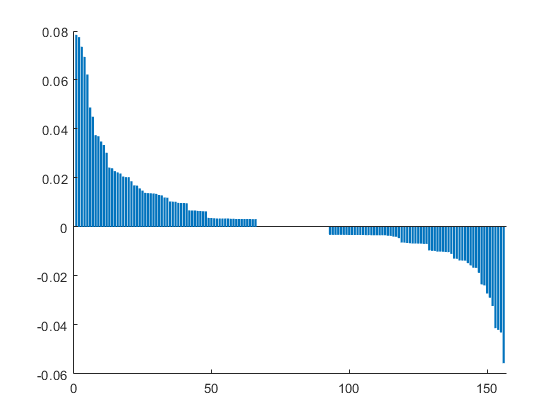


% plot 
tmp_acc = predict_acc(2:end);
del_acc = (tmp_acc - predict_acc(1:end-1))./predict_acc(1:end-1);
del_acc_genes = gene_name(2:end);

[~,idx] = sort(del_acc,'descend');
figure,bar(del_acc(idx))
box off


tbl_del_acc = array2table(del_acc(idx)','RowNames',del_acc_genes(idx));

Plot Distribution of the prediction accuracy

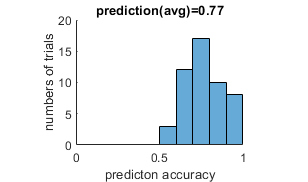

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure('Position',[680   796   308   182])

predict_acc_full = score_mat(:,end);

pbaspect([4 3 1]/4)
edges = [0:0.1:1];
histogram(predict_acc_full,edges)
title(strcat('prediction(avg)=',num2str(mean(predict_acc_full))))
xlabel('predicton accuracy'),ylabel('numbers of trials')
pbaspect([4 3 1]/4)
box off

confusion matrix

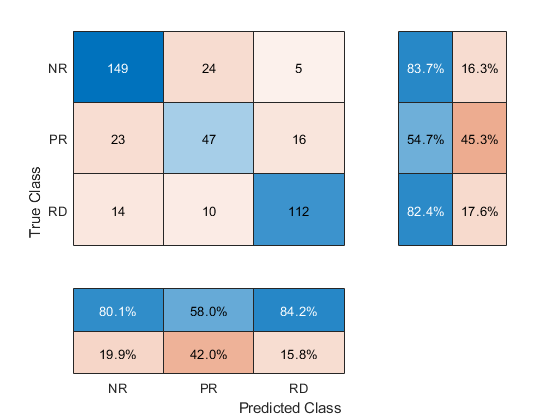

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tmp_prd(:,:) = predicted_class_label(:,:,end);
tmp_tr(:,:)= true_class_label(:,:,end);

[cfm,order] = confusionmat(tmp_tr(:),tmp_prd(:));
figure
cm = confusionchart(tmp_tr(:),tmp_prd(:), ...
    'ColumnSummary','column-normalized', ...
    'RowSummary','row-normalized');